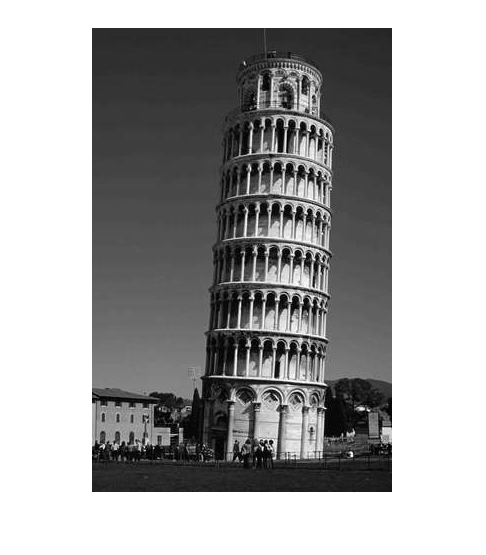

A=imread('/home/amrit/Documents/EE5175/EE5175_ISP_Lab1/Lab1/pisa_rotate.pgm');
imshow(A,[0,255])


[m,n] = size(A);

B=zeros(size(A));

xc=ceil((1+m)/2);
yc=ceil((1+m)/2);
deg=5.5

deg = 5.5000

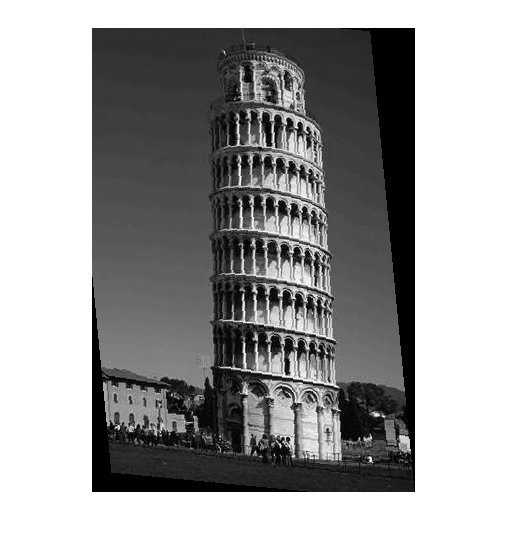

t=pi*deg/180;

for i=1:size(B,1)
    for j=1:size(B,1)
        xx=(i-xc)*cos(t)-(j-yc)*sin(t);
        yy=-(i-xc)*sin(t)+(j-yc)*cos(t);
        
        xx=round(xx)+xc;
        yy=round(yy)+yc;
        
        if (xx>=1 && yy>=1 && xx<=size(A,1) && yy<=size(A,2));
             B(i,j)=A(xx,yy);
             
        end
       
        
    end
end
imshow(B,[0,255])